# Regularized Zero Forcing Precoder

% Downlink
% Rate V.S. Correlation Parameter
% Linear Formation and Rectangular Formation


## Global Parameters

clc
clearvars

% Number of Antennas
M1 = 8;
M2 = 8;
M = M1 * M2;

% Number of Users
K = 10;

% Number of Taps in Time
taps = 4;

% Number of Taps in Frequency
freq = 20;

% Channel Use
use = 5;

% Time Interval
time = 100;
cyclic_prefix = 20;

% Time Shield
shield = taps + freq + 1;

% Normalized Distance
dn = 0.5;

% Identitty Matrix
IK = eye(K);

% Power
r = 10;
e = 10 * log10(r);

% Correlation Parameters
alpha = [0.0, 0.4, 0.7, 0.9, 0.99];
eta = [0, 50, 100, 200, 500];
mu = [0.0, pi / 6, pi / 4, pi / 3, pi / 2];

sample = 5;


## Distance Matrix

% Linear
for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end

fix_eta = 50;
fix_mu = 0;

for index = 1 : sample
    corr_exp_1d(:, :, index) = alpha(index) .^ dist;
    arg = fix_eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * fix_eta * sin(mu(index)) .* dist;
    arg = sqrt(arg);
    corr_bsl_1d_mu(:, :, index) = besseli(0, arg) ./ besseli(0, fix_eta);
    arg = eta(index) ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta(index) * sin(fix_mu) .* dist;
    arg = sqrt(arg);
    corr_bsl_1d_eta(:, :, index) = besseli(0, arg) ./ besseli(0, eta(index));
end
clear dist;

% Rectangular
i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end

for index = 1 : sample
    dist = sqrt(dist .* dn);
    corr_exp_2d(:, :, index) = alpha(index) .^ dist;
    arg = fix_eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * fix_eta * sin(mu(index)) .* dist;
    arg = sqrt(arg);
    corr_bsl_2d_mu(:, :, index) = besseli(0, arg) ./ besseli(0, fix_eta);
    arg = eta(index) ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta(index) * sin(fix_mu) .* dist;
    arg = sqrt(arg);
    corr_bsl_2d_eta(:, :, index) = besseli(0, arg) ./ besseli(0, eta(index));
end
clear dist;


## Channel Power Delay Profile

phase = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * phase(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * phase(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for index = 1 : sample
    
    exp_1D = corr_exp_1d(:, :, index);
    bsl_1D_mu = corr_bsl_1d_mu(:, :, index);
    bsl_1D_eta = corr_bsl_1d_eta(:, :, index);
    exp_2D = corr_exp_2d(:, :, index);
    bsl_2D_mu = corr_bsl_2d_mu(:, :, index);
    bsl_2D_eta = corr_bsl_2d_eta(:, :, index);

    for n = 1: use
        
        S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
    
        for l = 1: taps
            D1 = D(:, :, l) .^ (0.5);
            H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
            
            Hl_exp_1D(:, :, l, n) = conj((exp_1D ^ (0.5)) * H1) * D1;
            Hl_bsl_1D_mu(:, :, l, n) = conj((bsl_1D_mu ^ (0.5)) * H1) * D1;
            Hl_bsl_1D_eta(:, :, l, n) = conj((bsl_1D_eta ^ (0.5)) * H1) * D1;
            Hl_exp_2D(:, :, l, n) = conj((exp_2D ^ (0.5)) * H1) * D1;
            Hl_bsl_2D_mu(:, :, l, n) = conj((bsl_2D_mu ^ (0.5)) * H1) * D1;
            Hl_bsl_2D_eta(:, :, l, n) = conj((bsl_2D_eta ^ (0.5)) * H1) * D1;
        end
    
        Hv1 = fft(Hl_exp_1D(:, :, :, n), freq, 3);
        Hv2 = fft(Hl_bsl_1D_mu(:, :, :, n), freq, 3);
        Hv3 = fft(Hl_bsl_1D_eta(:, :, :, n), freq, 3);
        Hv4 = fft(Hl_exp_2D(:, :, :, n), freq, 3);
        Hv5 = fft(Hl_bsl_2D_mu(:, :, :, n), freq, 3);
        Hv6 = fft(Hl_bsl_2D_eta(:, :, :, n), freq, 3);
        bp = 2;
        if (0 <= alpha(index)) && (alpha(index) < 0.4)
            bp = 10;
        elseif (0.4 <= alpha(index)) && (alpha(index) < 0.7)
            bp = 10.7;
        elseif (0.7 <= alpha(index)) && (alpha(index) < 0.9)
            bp = 8.5;
        elseif (0.9 <= alpha(index)) && (alpha(index) < 0.99)
            bp = 2;
        else
            bp = 0.5;
        end
        for v = 1 : freq
            Fv = Hv1(:, :, v);
            Wv1(:, :, v) = Fv / (Fv' * Fv + bp * IK);
            clear Fv;
            Fv = Hv2(:, :, v);
            Wv2(:, :, v) = Fv / (Fv' * Fv + bp * IK);
            clear Fv;
            Fv = Hv3(:, :, v);
            Wv3(:, :, v) = Fv / (Fv' * Fv + bp * IK);
            clear Fv;
            Fv = Hv4(:, :, v);
            Wv4(:, :, v) = Fv / (Fv' * Fv + bp * IK);
            clear Fv;
            Fv = Hv5(:, :, v);
            Wv5(:, :, v) = Fv / (Fv' * Fv + bp * IK);
            clear Fv;
            Fv = Hv6(:, :, v);
            Wv6(:, :, v) = Fv / (Fv' * Fv + bp * IK);
            clear Fv;
        end
        Wl_exp_1D(:, :, :, n) = ifft(Wv1, freq, 3);
        Wl_bsl_1D_mu(:, :, :, n) = ifft(Wv2, freq, 3);
        Wl_bsl_1D_eta(:, :, :, n) = ifft(Wv3, freq, 3);
        Wl_exp_2D(:, :, :, n) = ifft(Wv4, freq, 3);
        Wl_bsl_2D_mu(:, :, :, n) = ifft(Wv5, freq, 3);
        Wl_bsl_2D_eta(:, :, :, n) = ifft(Wv6, freq, 3);
    
        [AX1(n)] = Signal_Power(freq, Wl_exp_1D(:, :, :, n));
        [AX2(n)] = Signal_Power(freq, Wl_bsl_1D_mu(:, :, :, n));
        [AX3(n)] = Signal_Power(freq, Wl_bsl_1D_eta(:, :, :, n));
        [AX4(n)] = Signal_Power(freq, Wl_exp_2D(:, :, :, n));
        [AX5(n)] = Signal_Power(freq, Wl_bsl_2D_mu(:, :, :, n));
        [AX6(n)] = Signal_Power(freq, Wl_bsl_2D_eta(:, :, :, n));
    
        % Composite Effect Matrix
        for k = 1: K
            for l = 0: (taps - 1)
                V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_exp_1D(:, :, l + 1, n) * IK(:, k);
                X1(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_bsl_1D_mu(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_1D_mu(:, :, l + 1, n) * IK(:, k);
                X2(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_bsl_1D_eta(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_1D_eta(:, :, l + 1, n) * IK(:, k);
                X3(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_exp_2D(:, :, l + 1, n) * IK(:, k);
                X4(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_bsl_2D_mu(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_2D_mu(:, :, l + 1, n) * IK(:, k);
                X5(l + 1) = V1' * V2;
                clear V1;
                clear V2;
                V1 = Hl_bsl_2D_eta(:, :, l + 1, n) * IK(:, k);
                V2 = Wl_bsl_2D_eta(:, :, l + 1, n) * IK(:, k);
                X6(l + 1) = V1' * V2;
                clear V1;
                clear V2;
            end
            EX1(k, n) = sum(X1);
            clear X1;
            EX2(k, n) = sum(X2);
            clear X2;
            EX3(k, n) = sum(X3);
            clear X3;
            EX4(k, n) = sum(X4);
            clear X4;
            EX5(k, n) = sum(X5);
            clear X5;
            EX6(k, n) = sum(X6);
            clear X6;
        end
    end
    a1 = mean(AX1);
    a2 = mean(AX2);
    a3 = mean(AX3);
    a4 = mean(AX4);
    a5 = mean(AX5);
    a6 = mean(AX6);
    
    clear AX1 AX2 AX3 AX4 AX5 AX6;
    
    % Received Signals and Desired Signals
    Y1 = zeros(K, time, use);
    Y2 = zeros(K, time, use);
    Y3 = zeros(K, time, use);
    Y4 = zeros(K, time, use);
    Y5 = zeros(K, time, use);
    Y6 = zeros(K, time, use);
    for n = 1 : use
        for k = 1 : K
            for l = 0 : (taps - 1)
                V1 = Hl_exp_1D(:, :, l + 1, n) * IK(:, k);
                V2 = Hl_bsl_1D_mu(:, :, l + 1, n) * IK(:, k);
                V3 = Hl_bsl_1D_eta(:, :, l + 1, n) * IK(:, k);
                V4 = Hl_exp_2D(:, :, l + 1, n) * IK(:, k);
                V5 = Hl_bsl_2D_mu(:, :, l + 1, n) * IK(:, k);
                V6 = Hl_bsl_2D_eta(:, :, l + 1, n) * IK(:, k);
                for m = 0: (freq - 1)
                    V7 = Wl_exp_1D(:, :, m + 1, n);
                    V8 = Wl_bsl_1D_mu(:, :, m + 1, n);
                    V9 = Wl_bsl_1D_eta(:, :, m + 1, n);
                    V10 = Wl_exp_2D(:, :, m + 1, n);
                    V11 = Wl_bsl_2D_mu(:, :, m + 1, n);
                    V12 = Wl_bsl_2D_eta(:, :, m + 1, n);
                    Y1(k, shield : time, n) = Y1(k, shield : time, n) + (V1' * V7 * S(:, (shield : time) - m - l, n));
                    Y2(k, shield : time, n) = Y2(k, shield : time, n) + (V2' * V8 * S(:, (shield : time) - m - l, n));
                    Y3(k, shield : time, n) = Y3(k, shield : time, n) + (V3' * V9 * S(:, (shield : time) - m - l, n));
                    Y4(k, shield : time, n) = Y4(k, shield : time, n) + (V4' * V10 * S(:, (shield : time) - m - l, n));
                    Y5(k, shield : time, n) = Y5(k, shield : time, n) + (V5' * V11 * S(:, (shield : time) - m - l, n));
                    Y6(k, shield : time, n) = Y6(k, shield : time, n) + (V6' * V12 * S(:, (shield : time) - m - l, n));
                end
            end
            X1(k, 1 : time, n) = mean(EX1(k, :)) * S(k, 1 : time, n) / a1;
            X2(k, 1 : time, n) = mean(EX2(k, :)) * S(k, 1 : time, n) / a2;
            X3(k, 1 : time, n) = mean(EX3(k, :)) * S(k, 1 : time, n) / a3;
            X4(k, 1 : time, n) = mean(EX4(k, :)) * S(k, 1 : time, n) / a4;
            X5(k, 1 : time, n) = mean(EX5(k, :)) * S(k, 1 : time, n) / a5;
            X6(k, 1 : time, n) = mean(EX6(k, :)) * S(k, 1 : time, n) / a6;
        end
    end
    
    % Effective Noise
    Z1(:, 1 : (shield - 1), :) = (Y1(:, 1 : (shield - 1), :) / a1);
    Z1(:, shield : time, :) = (Y1(:, shield : time, :) / a1) - X1(:, shield : time, :);
    Z2(:, 1 : (shield - 1), :) = (Y2(:, 1 : (shield - 1), :) / a2);
    Z2(:, shield : time, :) = (Y2(:, shield : time, :) / a2) - X2(:, shield : time, :);
    Z3(:, 1 : (shield - 1), :) = (Y3(:, 1 : (shield - 1), :) / a3);
    Z3(:, shield : time, :) = (Y3(:, shield : time, :) / a3) - X3(:, shield : time, :);
    Z4(:, 1 : (shield - 1), :) = (Y4(:, 1 : (shield - 1), :) / a4);
    Z4(:, shield : time, :) = (Y4(:, shield : time, :) / a4) - X4(:, shield : time, :);
    Z5(:, 1 : (shield - 1), :) = (Y5(:, 1 : (shield - 1), :) / a5);
    Z5(:, shield : time, :) = (Y5(:, shield : time, :) / a5) - X5(:, shield : time, :);
    Z6(:, 1 : (shield - 1), :) = (Y6(:, 1 : (shield - 1), :) / a6);
    Z6(:, shield : time, :) = (Y6(:, shield : time, :) / a6) - X6(:, shield : time, :);
    
    for n = 1: use
        for k = 1: K
            Sn1 = r * mean(abs(X1(k, :, n)) .^ 2);
            Sn2 = r * mean(abs(X2(k, :, n)) .^ 2);
            Sn3 = r * mean(abs(X3(k, :, n)) .^ 2);
            Sn4 = r * mean(abs(X4(k, :, n)) .^ 2);
            Sn5 = r * mean(abs(X5(k, :, n)) .^ 2);
            Sn6 = r * mean(abs(X6(k, :, n)) .^ 2);
            
            Vn1 = r * mean(abs(Z1(k,:, n)) .^ 2) + 1;
            Vn2 = r * mean(abs(Z2(k,:, n)) .^ 2) + 1;
            Vn3 = r * mean(abs(Z3(k,:, n)) .^ 2) + 1;
            Vn4 = r * mean(abs(Z4(k,:, n)) .^ 2) + 1;
            Vn5 = r * mean(abs(Z5(k,:, n)) .^ 2) + 1;
            Vn6 = r * mean(abs(Z6(k,:, n)) .^ 2) + 1;
            
            SNR1 = Sn1 / Vn1;
            SNR2 = Sn2 / Vn2;
            SNR3 = Sn3 / Vn3;
            SNR4 = Sn4 / Vn4;
            SNR5 = Sn5 / Vn5;
            SNR6 = Sn6 / Vn6;
            
            Rk1(k, n) = 0.5 * log2(1 + SNR1);
            Rk2(k, n) = 0.5 * log2(1 + SNR2);
            Rk3(k, n) = 0.5 * log2(1 + SNR3);
            Rk4(k, n) = 0.5 * log2(1 + SNR4);
            Rk5(k, n) = 0.5 * log2(1 + SNR5);
            Rk6(k, n) = 0.5 * log2(1 + SNR6);
        end
    end
    
    clear Z1 Z2 Z3 Z4 Z5 Z6;

    R1(index) = mean(sum(Rk1, 1), 2);
    R2(index) = mean(sum(Rk2, 1), 2);
    R3(index) = mean(sum(Rk3, 1), 2);
    R4(index) = mean(sum(Rk4, 1), 2);
    R5(index) = mean(sum(Rk5, 1), 2);
    R6(index) = mean(sum(Rk6, 1), 2);

    clear Sn1 Vn1 SNR1 Rk1;
    clear Sn2 Vn2 SNR2 Rk2;
    clear Sn3 Vn3 SNR3 Rk3;
    clear Sn4 Vn4 SNR4 Rk4;
    clear Sn5 Vn5 SNR5 Rk5;
    clear Sn6 Vn6 SNR6 Rk6;
    
    clear Wv1 Wv2 Wv3 Wv4 Wv5 Wv6;
    clear Hl_exp_1D Hl_bsl_1D_mu Hl_bsl_1D_eta Hl_exp_2D Hl_bsl_2D_mu Hl_bsl_2D_eta;
    clear Wl_exp_1D Wl_bsl_1D_mu Wl_bsl_1D_eta Wl_exp_2D Wl_bsl_2D_mu Wl_bsl_2D_eta;
    
    clear EX1 Ex2 EX3 EX4 EX5 EX6;
    clear X1 X2 X3 X4 X5 X6;
    
    clear S Z;
    
end

factor = (time) / (time + cyclic_prefix);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;
R5 = factor * R5;
R6 = factor * R6;


## Visualization

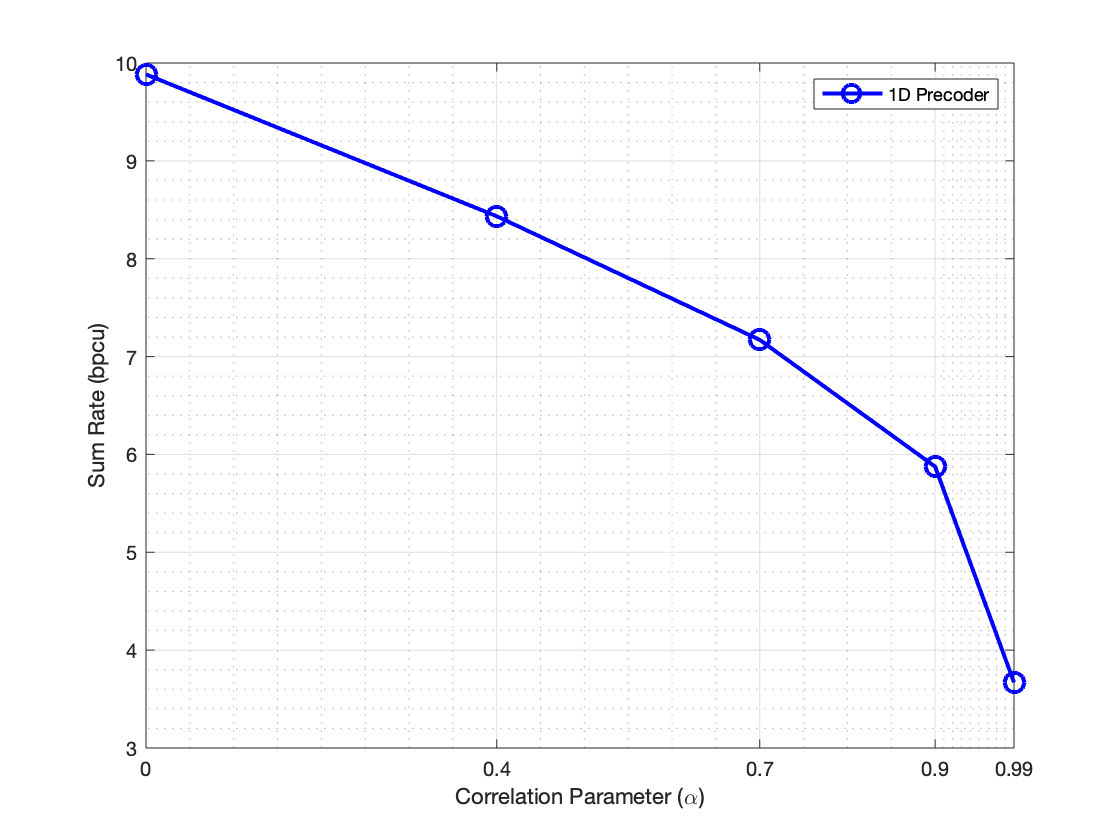

name1 = '1D Precoder';
name2 = strcat('1D Precoder, \eta=', num2str(fix_eta));
name3 = strcat('1D Precoder, \mu=', num2str(fix_mu));
name4 = '2D Precoder';
name5 = strcat('2D Precoder, \eta=', num2str(fix_eta));
name6 = strcat('2D Precoder, \mu=', num2str(fix_mu));

x_label_1 = 'Correlation Parameter (\alpha)';
x_label_2 = 'Correlation Parameter (\mu)';
x_label_3 = 'Correlation Parameter (\eta)';
y_label = 'Sum Rate (bpcu)';

style_1 = '-bo';
style_2 = '-ro';

figure;
plot(alpha, R1, style_1, 'DisplayName', name1, 'MarkerSize', 10);

xlabel(x_label_1, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(alpha);
xlim([alpha(1), alpha(sample)]);
legend();
grid on;
grid minor;

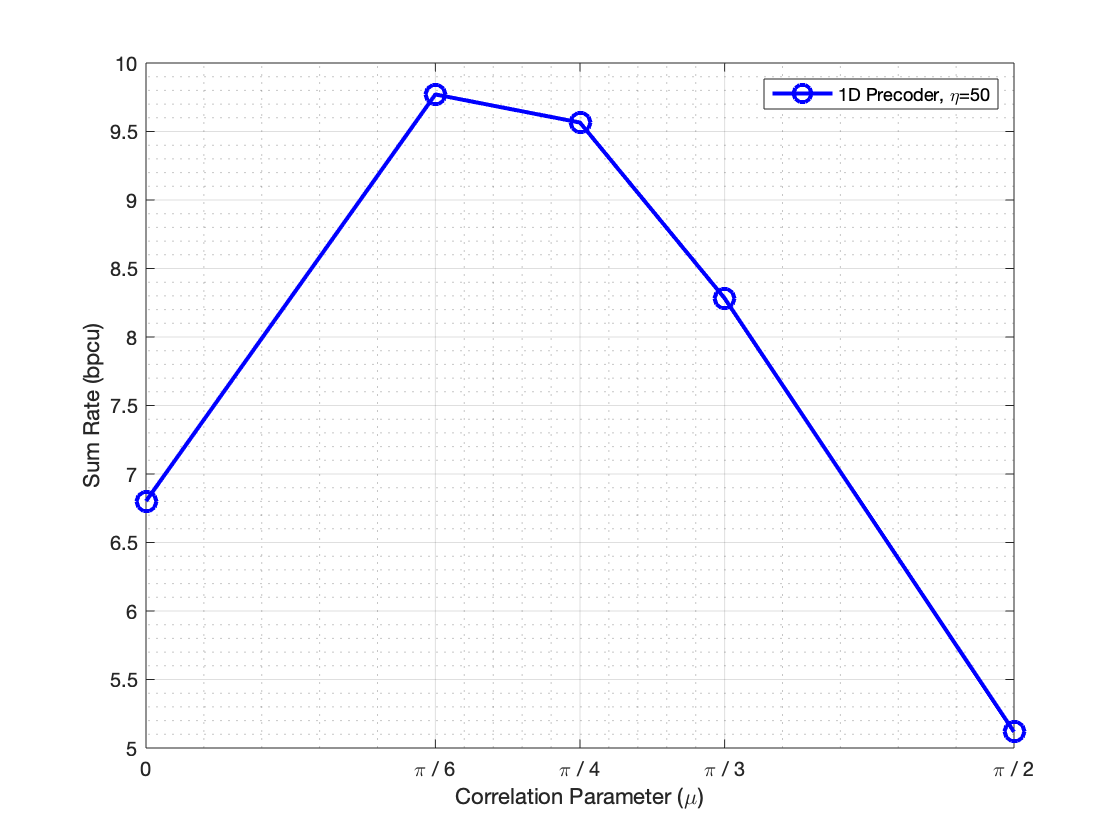



figure;
plot(mu, R2, style_1, 'DisplayName', name2, 'MarkerSize', 10);

xlabel(x_label_2, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(mu);
xticklabels({'0', '\pi / 6', '\pi / 4', '\pi / 3', '\pi / 2'})
xlim([mu(1), mu(sample)]);
legend();
grid on;
grid minor;

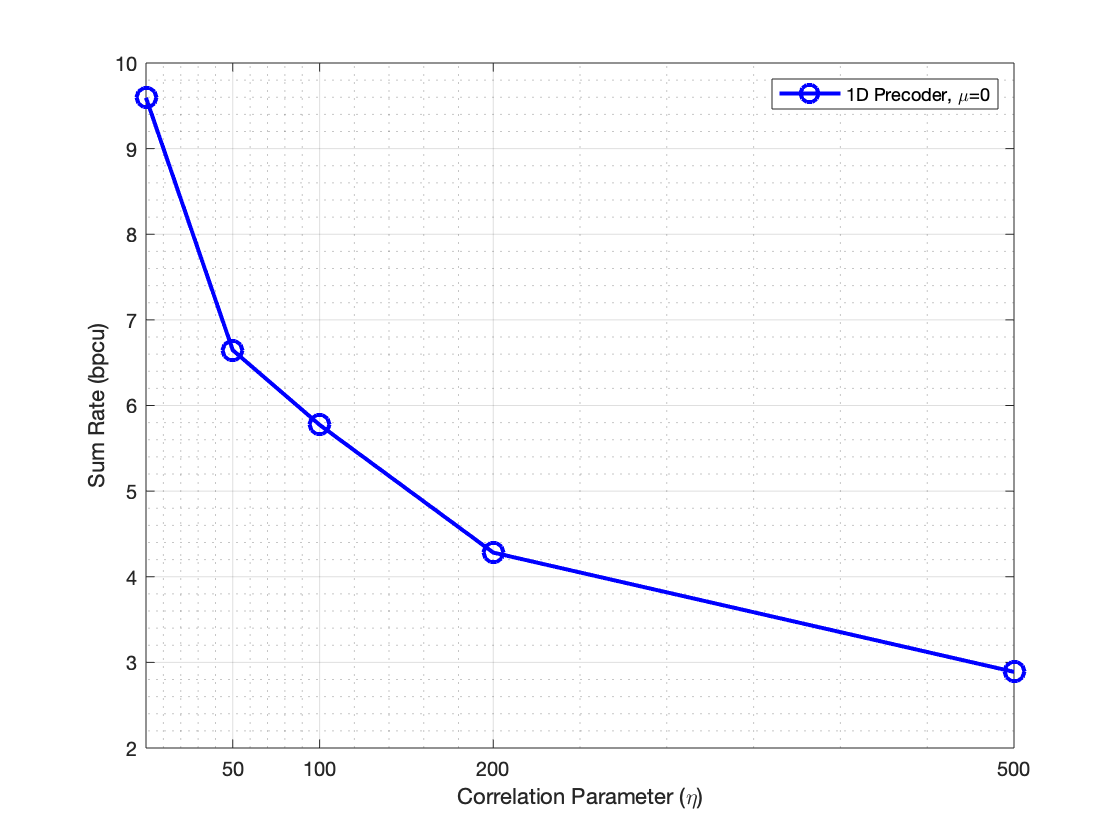



figure;
plot(eta, R3, style_1, 'DisplayName', name3, 'MarkerSize', 10);

xlabel(x_label_3, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(eta(2 : sample));
xlim([eta(1), eta(sample)]);
legend();
grid on;
grid minor;

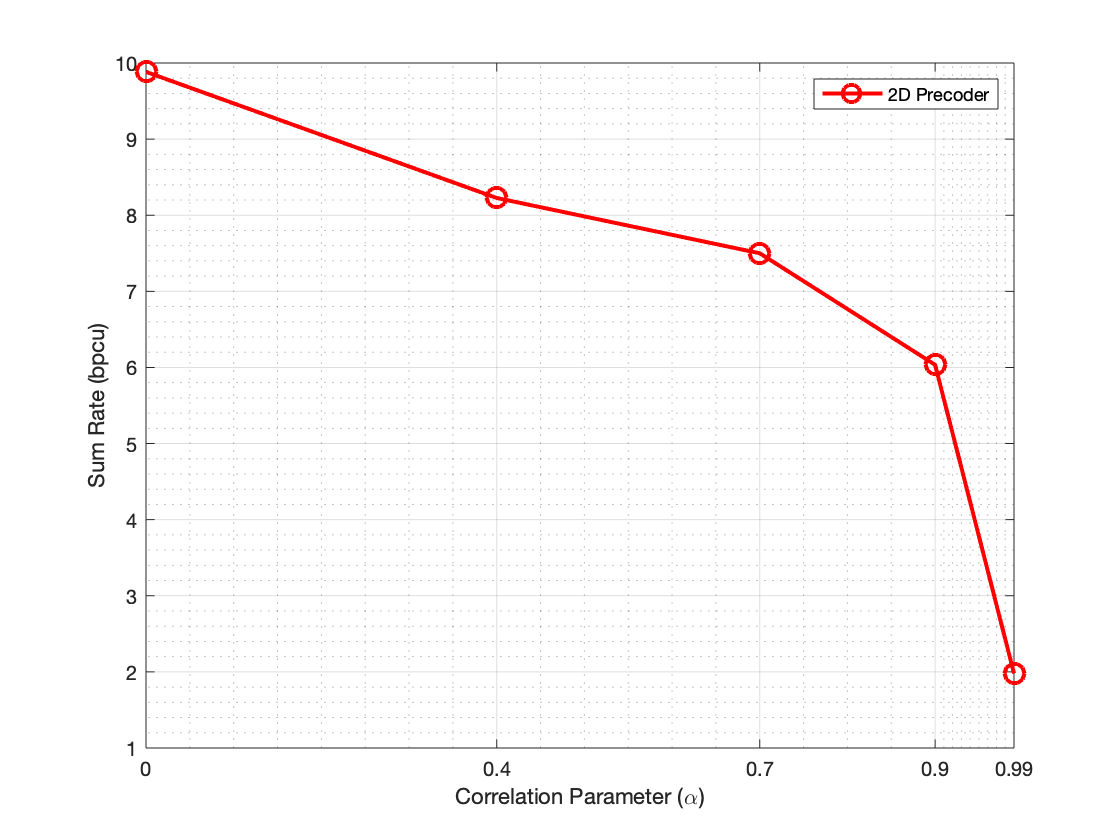


figure;
plot(alpha, R4, style_2, 'DisplayName', name4, 'MarkerSize', 10);

xlabel(x_label_1, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(alpha);
xlim([alpha(1), alpha(sample)]);
legend();
grid on;
grid minor;

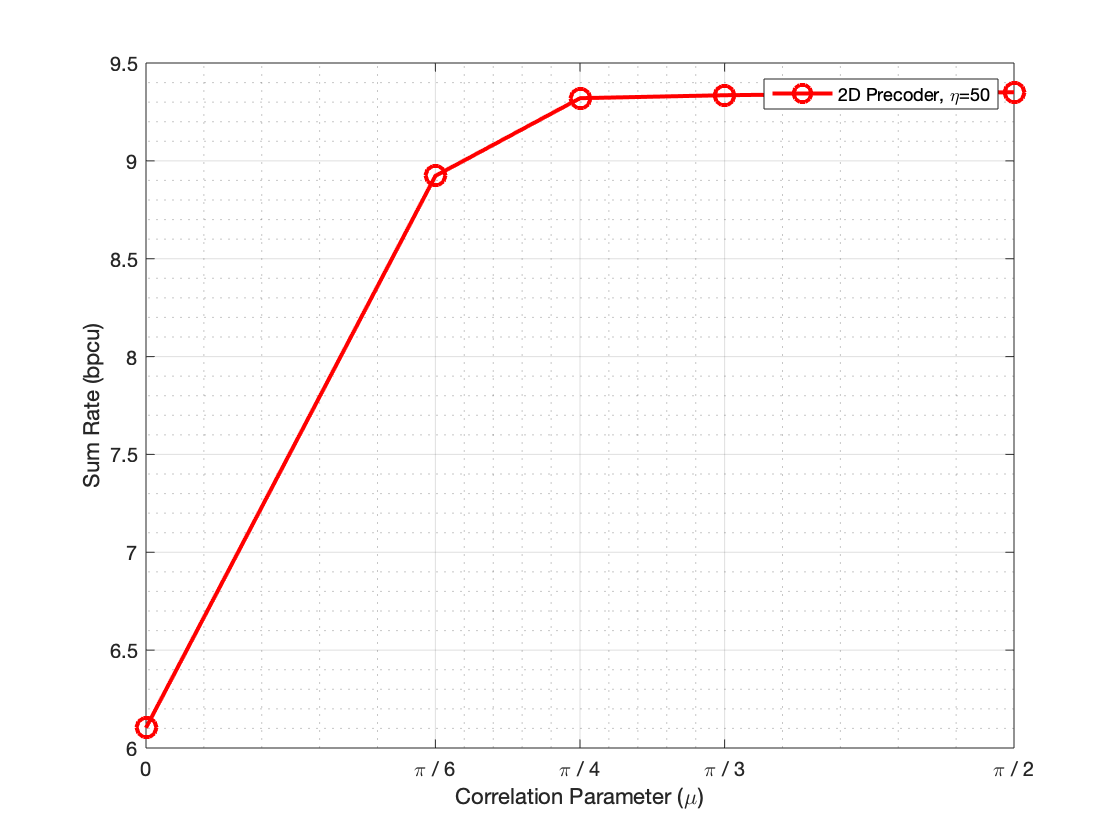



figure;
plot(mu, R5, style_2, 'DisplayName', name5, 'MarkerSize', 10);

xlabel(x_label_2, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(mu);
xticklabels({'0', '\pi / 6', '\pi / 4', '\pi / 3', '\pi / 2'})
xlim([mu(1), mu(sample)]);
legend();
grid on;
grid minor;

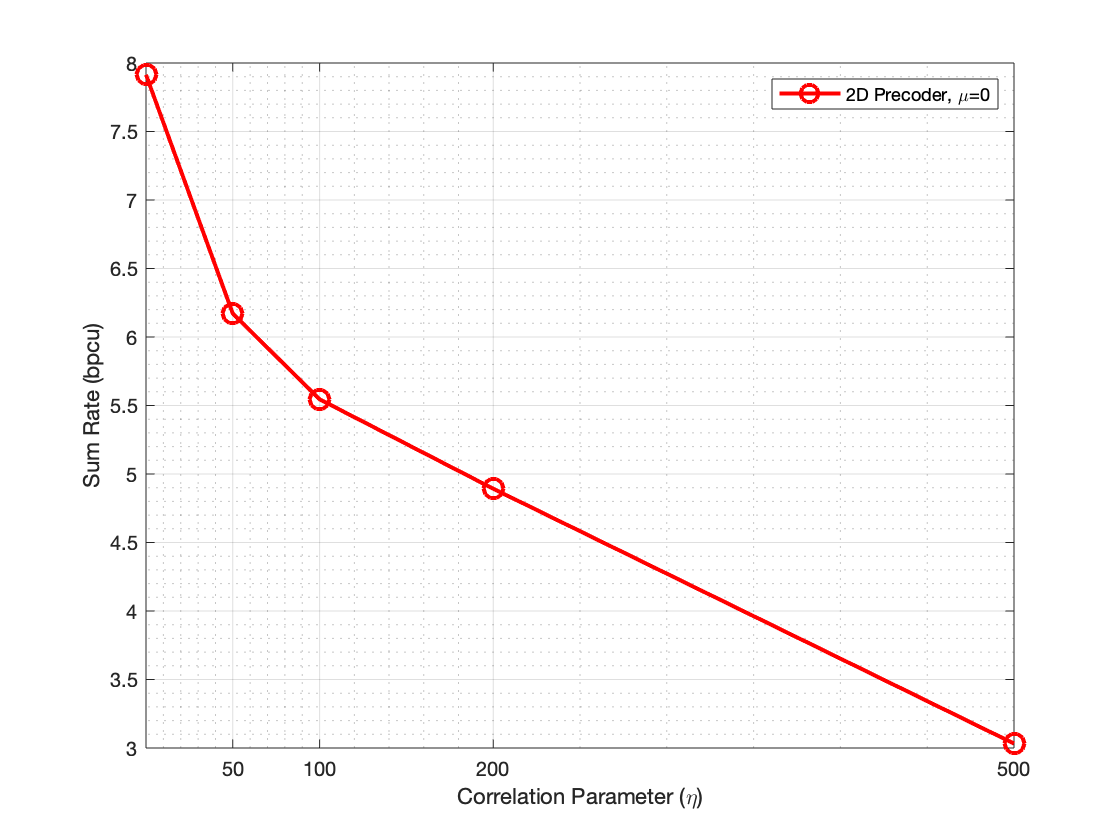



figure;
plot(eta, R6, style_2, 'DisplayName', name6, 'MarkerSize', 10);

xlabel(x_label_3, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
xticks(eta(2 : sample));
xlim([eta(1), eta(sample)]);
legend();
grid on;
grid minor;